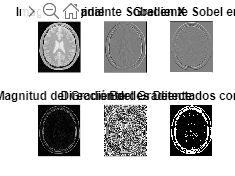

% Paso 1: Cargar la imagen y convertirla a escala de grises
image = imread('imagen_gris.jpeg');  % Cargar la imagen desde el archivo especificado
grayImage = rgb2gray(image);  % Convertir la imagen a escala de grises

% Paso 2: Definir los kernels de Sobel para detección de bordes en x e y
Gx = [-1 0 1; -2 0 2; -1 0 1];  % Kernel para detección de bordes horizontales
Gy = [1 2 1; 0 0 0; -1 -2 -1];  % Kernel para detección de bordes verticales

% Paso 3: Aplicar los kernels de Sobel a la imagen en escala de grises
sobelX = conv2(double(grayImage), Gx, 'same');  % Convolución con el kernel Gx
sobelY = conv2(double(grayImage), Gy, 'same');  % Convolución con el kernel Gy

% Paso 4: Calcular la magnitud del gradiente
sobelCombined = sqrt(sobelX.^2 + sobelY.^2);  % Magnitud del gradiente combinada

% Paso 5: Calcular la dirección del gradiente
gradientDirection = atan2(sobelY, sobelX);  % Dirección del gradiente

% Paso 6: Umbralizar la magnitud del gradiente para obtener bordes binarios
threshold = 100;  % Ajustar este valor según sea necesario
binaryEdges = sobelCombined > threshold;  % Crear imagen binaria de bordes

% Paso 7: Mostrar los resultados en una figura
figure;  % Crear una nueva figura para mostrar los resultados

% Mostrar la imagen original
subplot(2, 3, 1);  
imshow(grayImage);  
title('Imagen Original');  

% Mostrar el gradiente en X
subplot(2, 3, 2);  
imshow(sobelX, []);  
title('Gradiente Sobel en X');  

% Mostrar el gradiente en Y
subplot(2, 3, 3);  
imshow(sobelY, []);  
title('Gradiente Sobel en Y');  

% Mostrar la magnitud del gradiente
subplot(2, 3, 4);  
imshow(sobelCombined, []);  
title('Magnitud del Gradiente');  

% Mostrar la dirección del gradiente
subplot(2, 3, 5);  
imshow(gradientDirection, []);  
title('Dirección del Gradiente');  

% Mostrar los bordes detectados con Sobel
subplot(2, 3, 6);  
imshow(binaryEdges);  
title('Bordes Detectados con Sobel');  

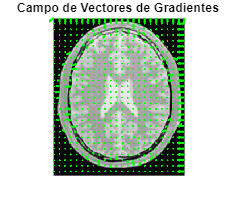

% Mostrar el campo de vectores de los gradientes
figure;  % Crear una nueva figura para el campo de vectores
imshow(grayImage);  % Mostrar la imagen original en escala de grises
title('Campo de Vectores de Gradientes');  % Añadir título
hold on;  % Mantener la imagen para superponer el campo de vectores
[rows, cols] = size(grayImage);  % Obtener el tamaño de la imagen
[x, y] = meshgrid(1:cols, 1:rows);  % Crear una malla de coordenadas

% Reducir la cantidad de vectores para una visualización más clara
step = 10;  % Espaciado entre vectores
quiver(x(1:step:end, 1:step:end), y(1:step:end, 1:step:end), ...
       sobelX(1:step:end, 1:step:end), sobelY(1:step:end, 1:step:end), ...
       'g', 'LineWidth', 1.5, 'MaxHeadSize', 2);
hold off;  % Soltar la imagen


% Paso 1: Cargar la imagen y convertirla a escala de grises
image = imread('CRAI.jpeg');  % Cargar la imagen desde el archivo especificado
grayImage = rgb2gray(image);  % Convertir la imagen a escala de grises

% Paso 2: Definir los kernels de Sobel para detección de bordes en x e y
Gx = [-1 0 1; -2 0 2; -1 0 1];  % Kernel para detección de bordes horizontales
Gy = [1 2 1; 0 0 0; -1 -2 -1];  % Kernel para detección de bordes verticales

% Paso 3: Aplicar los kernels de Sobel a la imagen en escala de grises
sobelX = conv2(double(grayImage), Gx, 'same');  % Convolución con el kernel Gx
sobelY = conv2(double(grayImage), Gy, 'same');  % Convolución con el kernel Gy

% Paso 4: Calcular la magnitud del gradiente
sobelCombined = sqrt(sobelX.^2 + sobelY.^2);  % Magnitud del gradiente combinada

% Paso 5: Calcular la dirección del gradiente
gradientDirection = atan2(sobelY, sobelX);  % Dirección del gradiente

% Paso 6: Umbralizar la magnitud del gradiente para obtener bordes binarios
threshold = 100;  % Ajustar este valor según sea necesario
binaryEdges = sobelCombined > threshold;  % Crear imagen binaria de bordes

% Paso 7: Mostrar los resultados en una figura
figure;  % Crear una nueva figura para mostrar los resultados

% Mostrar la imagen original
subplot(2, 3, 1);  
imshow(grayImage);  
title('Imagen Original');  

% Mostrar el gradiente en X
subplot(2, 3, 2);  
imshow(sobelX, []);  
title('Gradiente Sobel en X');  

% Mostrar el gradiente en Y
subplot(2, 3, 3);  
imshow(sobelY, []);  
title('Gradiente Sobel en Y');  

% Mostrar la magnitud del gradiente
subplot(2, 3, 4);  
imshow(sobelCombined, []);  
title('Magnitud del Gradiente');  

% Mostrar la dirección del gradiente
subplot(2, 3, 5);  
imshow(gradientDirection, []);  
title('Dirección del Gradiente');  

% Mostrar los bordes detectados con Sobel
subplot(2, 3, 6);  
imshow(binaryEdges);  
title('Bordes Detectados con Sobel');  
% Mostrar el campo de vectores de los gradientes
figure;  % Crear una nueva figura para el campo de vectores
imshow(grayImage);  % Mostrar la imagen original en escala de grises
title('Campo de Vectores de Gradientes');  % Añadir título
hold on;  % Mantener la imagen para superponer el campo de vectores
[rows, cols] = size(grayImage);  % Obtener el tamaño de la imagen
[x, y] = meshgrid(1:cols, 1:rows);  % Crear una malla de coordenadas

% Reducir la cantidad de vectores para una visualización más clara
step = 10;  % Espaciado entre vectores
quiver(x(1:step:end, 1:step:end), y(1:step:end, 1:step:end), ...
       sobelX(1:step:end, 1:step:end), sobelY(1:step:end, 1:step:end), ...
       'g', 'LineWidth', 1.5, 'MaxHeadSize', 2);
hold off;  % Soltar la imagen

% Paso 1: Cargar la imagen y convertirla a escala de grises
image = imread('Restaurante.jpeg');  % Cargar la imagen desde el archivo especificado
grayImage = rgb2gray(image);  % Convertir la imagen a escala de grises

% Paso 2: Definir los kernels de Sobel para detección de bordes en x e y
Gx = [-1 0 1; -2 0 2; -1 0 1];  % Kernel para detección de bordes horizontales
Gy = [1 2 1; 0 0 0; -1 -2 -1];  % Kernel para detección de bordes verticales

% Paso 3: Aplicar los kernels de Sobel a la imagen en escala de grises
sobelX = conv2(double(grayImage), Gx, 'same');  % Convolución con el kernel Gx
sobelY = conv2(double(grayImage), Gy, 'same');  % Convolución con el kernel Gy

% Paso 4: Calcular la magnitud del gradiente
sobelCombined = sqrt(sobelX.^2 + sobelY.^2);  % Magnitud del gradiente combinada

% Paso 5: Calcular la dirección del gradiente
gradientDirection = atan2(sobelY, sobelX);  % Dirección del gradiente

% Paso 6: Umbralizar la magnitud del gradiente para obtener bordes binarios
threshold = 100;  % Ajustar este valor según sea necesario
binaryEdges = sobelCombined > threshold;  % Crear imagen binaria de bordes

% Paso 7: Mostrar los resultados en una figura
figure;  % Crear una nueva figura para mostrar los resultados

% Mostrar la imagen original
subplot(2, 3, 1);  
imshow(grayImage);  
title('Imagen Original');  

% Mostrar el gradiente en X
subplot(2, 3, 2);  
imshow(sobelX, []);  
title('Gradiente Sobel en X');  

% Mostrar el gradiente en Y
subplot(2, 3, 3);  
imshow(sobelY, []);  
title('Gradiente Sobel en Y');  

% Mostrar la magnitud del gradiente
subplot(2, 3, 4);  
imshow(sobelCombined, []);  
title('Magnitud del Gradiente');  

% Mostrar la dirección del gradiente
subplot(2, 3, 5);  
imshow(gradientDirection, []);  
title('Dirección del Gradiente');  

% Mostrar los bordes detectados con Sobel
subplot(2, 3, 6);  
imshow(binaryEdges);  
title('Bordes Detectados con Sobel');  
% Mostrar el campo de vectores de los gradientes
figure;  % Crear una nueva figura para el campo de vectores
imshow(grayImage);  % Mostrar la imagen original en escala de grises
title('Campo de Vectores de Gradientes');  % Añadir título
hold on;  % Mantener la imagen para superponer el campo de vectores
[rows, cols] = size(grayImage);  % Obtener el tamaño de la imagen
[x, y] = meshgrid(1:cols, 1:rows);  % Crear una malla de coordenadas

% Reducir la cantidad de vectores para una visualización más clara
step = 10;  % Espaciado entre vectores
quiver(x(1:step:end, 1:step:end), y(1:step:end, 1:step:end), ...
       sobelX(1:step:end, 1:step:end), sobelY(1:step:end, 1:step:end), ...
       'g', 'LineWidth', 1.5, 'MaxHeadSize', 2);
hold off;  % Soltar la imagen
